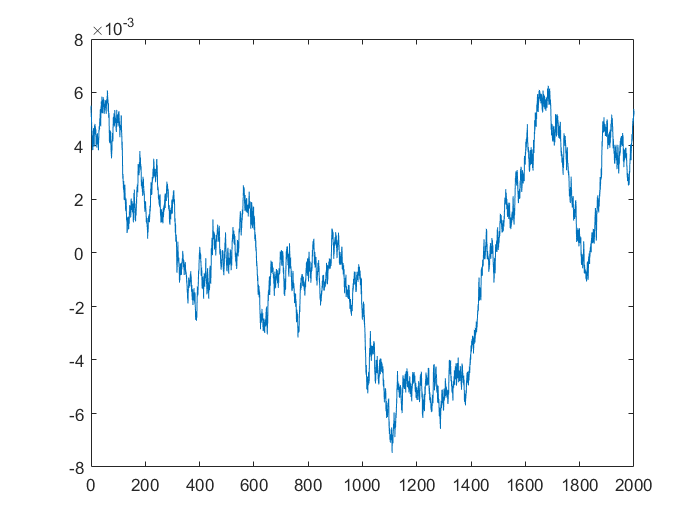

k = 3; % Values For ISO Road A-B Roughness Classification, from 3 to 9
N  = 17000; %  Number of data points
L  = 2000;  % Length Of Road Profile (m)
B  = L/N ; % Sampling Interval (m)
dn = 1/L;  % Frequency Band
n0 = 0.01;        % Spatial Frequency (cycles/m)
n  = dn : dn : N*dn; % Spatial Frequency Band
phi =  2*pi*rand(size(n)); % Random Phase Angle
Amp1 = sqrt(dn)*(2^k)*(1e-3)*(n0./n); % Amplitude for Road  Class A-B
x = 0:B:L-B; % Abscissa Variable from 0 to L
hx = zeros(size(x));
for i=1:length(x)
    hx(i) = sum(Amp1.*cos(2*pi*n*x(i)+ phi));
end
plot(x,hx)

% xlim([-20 50])
a=hx;
t=table(a,'VariableNames',{'a'});
writetable(t, 'Iso3.txt')